# Taratura manuale dell'anello di velocità

Determinare $C(s)$ in modo che soddisfi una frequenza di taglio desirata

In quest'esempio il controllore è un PI


$$C(s)=PI(s)=\frac{K_p\cdot s+K_i}{s}=K_p\left(1+\frac{1}{T_i s}\right)=K_p \frac{T_i s +1}{T_i s}$$


il processo è la funzione di trasferimento, in questo caso coppia - velocità lato motore

**Nota Gruppo 7: **se abbiamo più modelli, cambia l'id (000)

clear all;close all;clc;
load ../data/models/000/model_joint3.mat
Ts=1e-3;
s=tf('s');
sys_vel_motore=tf(modello_continuo);

Con funzione di trasferimento

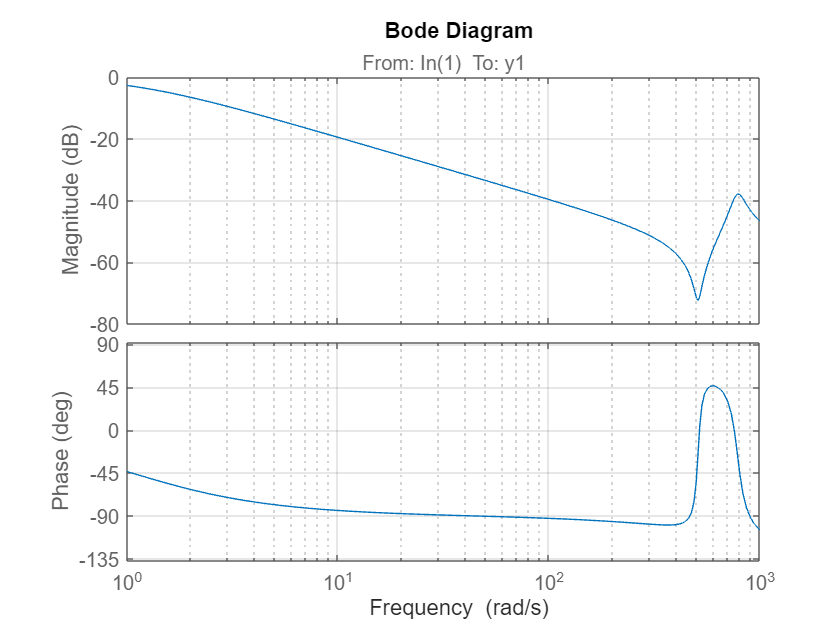

figure
bode(sys_vel_motore)
xlim([1 1000])
grid on

Vorrei un $\omega_c$ prossima all'antirisonanza (che è attorno a 200 rad/s)

wc=50; % da tarare -> il più grande possibile

L'azione integrale mi sfasa, la metto almeno una decade prima.

wi=wc/20; % pulsazione azione integrale -> errore a regime nullo, il suo contributo deve essere a bassa freq.
Ti=1/wi;

Il mio controllore sarà


$$C(s)=K_p \left(1+1/(Ti\cdot s)\right)=K_p C_o(s)$$


con $C_o(s)=$

s=tf('s');
Co=1+1/(Ti*s);

Calcolo $K_p$ in modo che $C(s)*P(s)=K_p \left(C_o(s)*P(s)\right)$ abbia modulo 1 in $\omega_c$. 

$|K_p \left(C_o(j\omega_c)*P(j\omega_c)\right)|=1 $ quindi $K_p=1/| \left(C_o(j\omega_c)*P(j\omega_c)\right)|$

Kp=1/abs(freqresp(Co*sys_vel_motore,wc)); % kp taglia lo 0 dB nel punto desiderato
C=Kp*Co

C =
 
  18.94 s + 47.35
  ---------------
       0.4 s
 
Continuous-time transfer function.
Model Properties


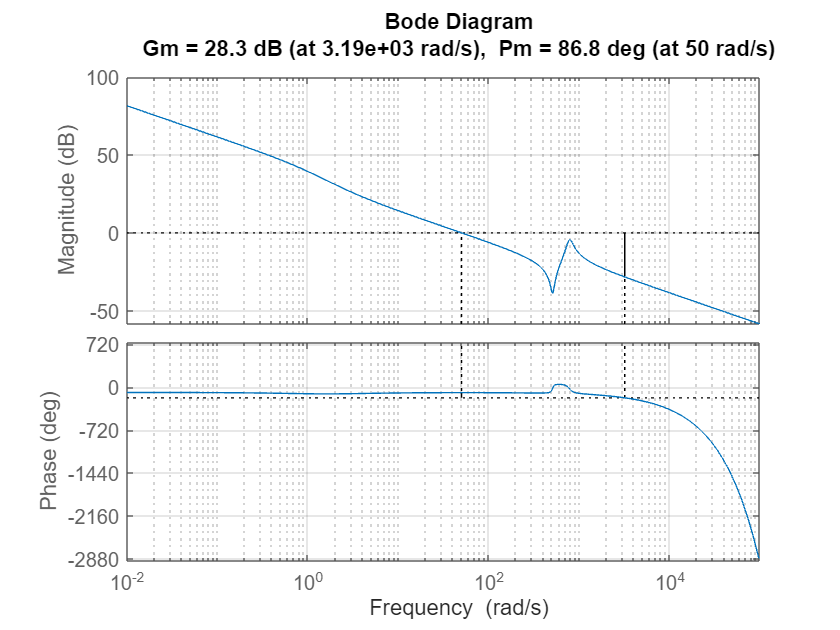

figure
margin(C*sys_vel_motore)
grid on

Il diagramma di bode taglia più volte, meglio aggiungere un filtro per abbassare il picco.

#### Filtro Notch

Un filtro notch è un'elimina banda. La zona da eliminare è 

damp(sys_vel_motore) % dice i poli

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.05e+00                 1.00e+00       1.05e+00         9.49e-01    
 -5.67e+01 + 7.81e+02i     7.25e-02       7.83e+02         1.76e-02    
 -5.67e+01 - 7.81e+02i     7.25e-02       7.83e+02         1.76e-02    


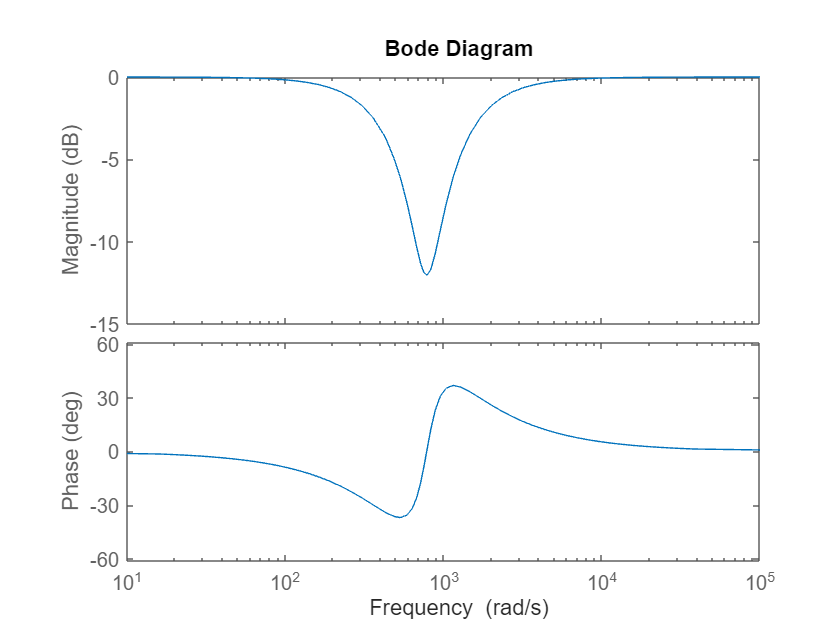

wn=783;% 1)546 2)647 3)783
xci_z=0.2; % più è piccolo e più la conca è profonda e più è stretto %aggiustate xci_z e xci_p per rendere il filtro più o meno selettivo
xci_p=0.8;% circa 0.7 , 0.8
notch=(s^2+2*xci_z*wn*s+wn^2)/(s^2+2*xci_p*wn*s+wn^2); % per iniziare posso mettere gli zeri del notch come i poli che causano la risonanza e poi
% aggiustarli un po'
figure
bode(notch)

Per il PI, il "nuovo" sistema da controllare è

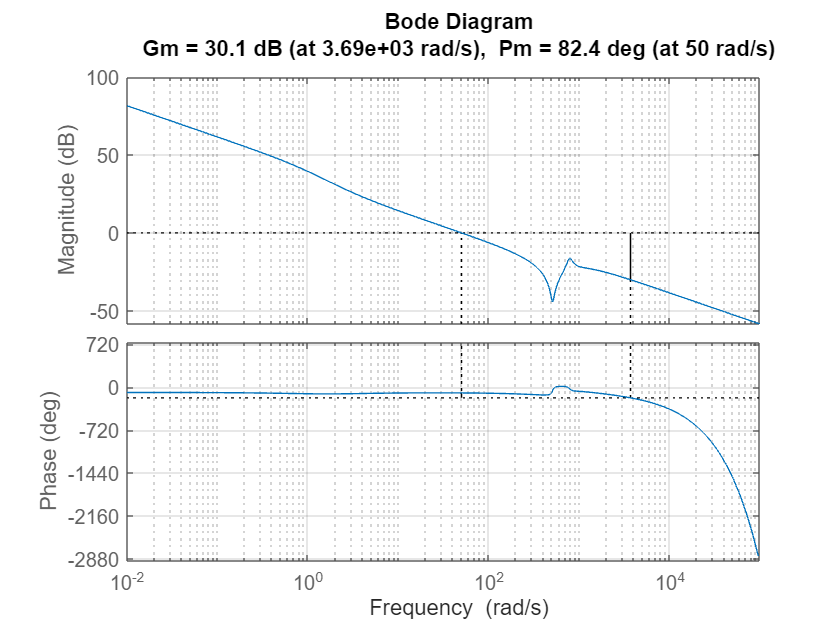

P=sys_vel_motore*notch; % posso aggiungere anche un filtro passa-basso circa una decade dopo wc, P=sys_vel_motore*notch*passabasso
Kp=1/abs(freqresp(Co*P,wc));
C=Kp*Co;
figure
margin(C*P)
grid on

Potrei voler aggiungere altri poli (ad esempio un passa basso)